clear; clc; close all;

%% PARAMETERS
fs = 200000;          % target sampling frequency
fc = 50000;           % carrier frequency
B = 1000;             % message bandwidth limit = 1 kHz
mu = 0.8;             % modulation index for DSB-TC

%% LOAD AUDIO FILE
[x, fs0] = audioread('Amna.wav');   % change file name here

% make mono if stereo
if size(x,2) > 1
    x = mean(x,2);
end

% keep EXACTLY first 3 seconds
x = x(1:3*fs0);

%% TIME AXIS FOR ORIGINAL
t0 = (0:length(x)-1)/fs0;

%% LISTEN TO ORIGINAL
disp('Playing ORIGINAL signal...');

Playing ORIGINAL signal...


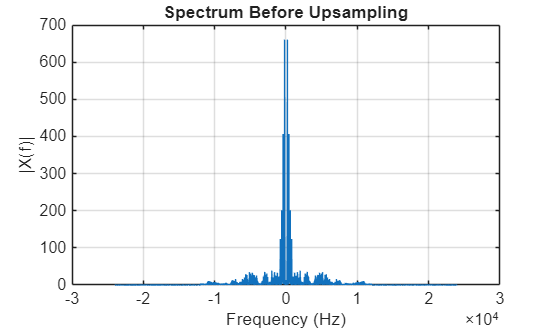

soundsc(x, fs0);
pause(4);

%% SPECTRUM BEFORE UPSAMPLING
N0 = length(x);
f0 = linspace(-fs0/2, fs0/2, N0);
X0 = fftshift(abs(fft(x)));

figure;
plot(f0, X0);
title('Spectrum Before Upsampling');
xlabel('Frequency (Hz)');
ylabel('|X(f)|');
grid on;


%% UPSAMPLE TO 200 kHz
x_up = resample(x, fs, fs0);
t = (0:length(x_up)-1)/fs;
t = t(:);
x_up = x_up(:);

%% LISTEN TO UPSAMPLED SIGNAL
disp('Playing UPSAMPLED signal...');

Playing UPSAMPLED signal...


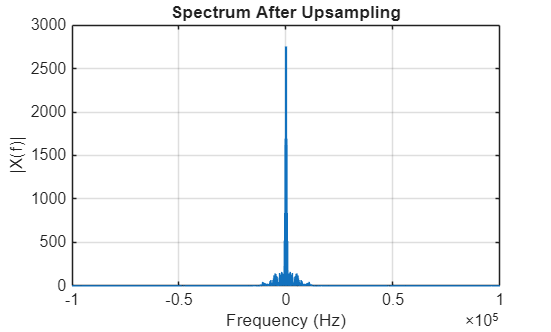

soundsc(x_up, fs);
pause(4);

%% SPECTRUM AFTER UPSAMPLING
N1 = length(x_up);
f1 = linspace(-fs/2, fs/2, N1);
X1 = fftshift(abs(fft(x_up)));

figure;
plot(f1, X1);
title('Spectrum After Upsampling');
xlabel('Frequency (Hz)');
ylabel('|X(f)|');
grid on;


%% LOW-PASS FILTER TO 1 kHz
[b, a] = butter(5, B/(fs/2));
x_filt = filter(b, a, x_up);

%% LISTEN TO FILTERED SIGNAL
disp('Playing FILTERED/baseband signal...');

Playing FILTERED/baseband signal...


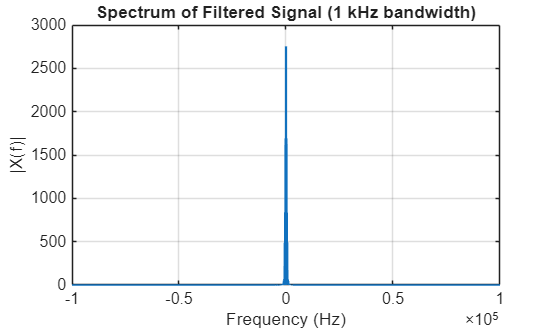

soundsc(x_filt, fs);
pause(4);

%% SPECTRUM OF FILTERED SIGNAL
Xf = fftshift(abs(fft(x_filt)));

figure;
plot(f1, Xf);
title('Spectrum of Filtered Signal (1 kHz bandwidth)');
xlabel('Frequency (Hz)');
ylabel('|X(f)|');
grid on;

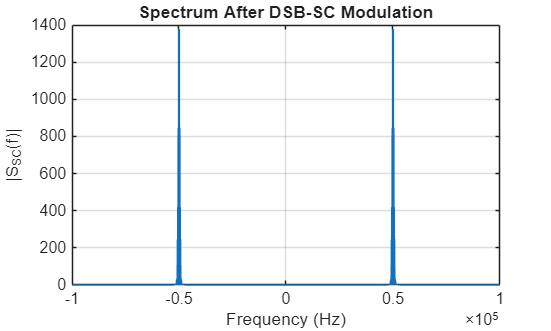


%% =========================
%% DSB-SC MODULATION
%% =========================
carrier = cos(2*pi*fc*t);
s_sc = x_filt .* carrier;

%% SPECTRUM OF DSB-SC
Ssc = fftshift(abs(fft(s_sc)));

figure;
plot(f1, Ssc);
title('Spectrum After DSB-SC Modulation');
xlabel('Frequency (Hz)');
ylabel('|S_{SC}(f)|');
grid on;

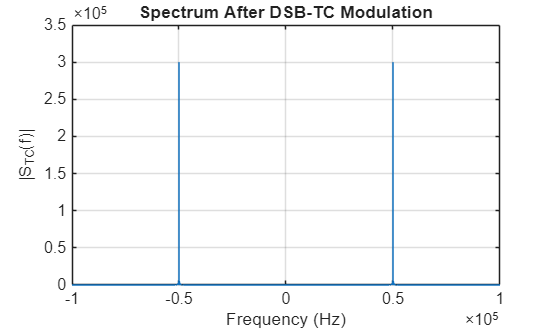


%% =========================
%% DSB-TC MODULATION
%% =========================
x_norm = x_filt / max(abs(x_filt) + eps);
s_tc = (1 + mu*x_norm) .* carrier;

%% SPECTRUM OF DSB-TC
Stc = fftshift(abs(fft(s_tc)));

figure;
plot(f1, Stc);
title('Spectrum After DSB-TC Modulation');
xlabel('Frequency (Hz)');
ylabel('|S_{TC}(f)|');
grid on;


%% SAVE .MAT FILES
Emna_sc = s_sc;
Emna_tc = s_tc;

save('Emna_sc.mat', 'Emna_sc', 'fs');
save('Emna_tc.mat', 'Emna_tc', 'fs');

%% =========================
%% DSB-SC DEMODULATION
%% =========================
r_sc = s_sc .* (2*cos(2*pi*fc*t));
x_rec_sc = filter(b, a, r_sc);

% normalize for listening
x_rec_sc = x_rec_sc / max(abs(x_rec_sc) + eps);

%% LISTEN TO DSB-SC DEMODULATED SIGNAL
disp('Playing DEMODULATED DSB-SC signal...');

Playing DEMODULATED DSB-SC signal...


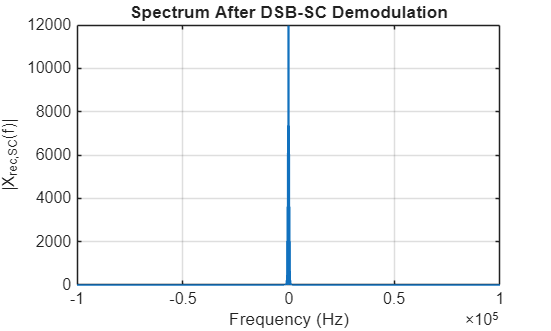

soundsc(x_rec_sc, fs);
pause(4);

%% SPECTRUM AFTER DSB-SC DEMODULATION
Xrec_sc = fftshift(abs(fft(x_rec_sc)));

figure;
plot(f1, Xrec_sc);
title('Spectrum After DSB-SC Demodulation');
xlabel('Frequency (Hz)');
ylabel('|X_{rec,SC}(f)|');
grid on;


%% =========================
%% DSB-TC DEMODULATION
%% =========================
r_tc = s_tc .* (2*cos(2*pi*fc*t));
x_rec_tc = filter(b, a, r_tc);

% remove DC for fairer recovered signal
x_rec_tc = x_rec_tc - mean(x_rec_tc);

% normalize for listening
x_rec_tc = x_rec_tc / max(abs(x_rec_tc) + eps);

%% LISTEN TO DSB-TC DEMODULATED SIGNAL
disp('Playing DEMODULATED DSB-TC signal...');

Playing DEMODULATED DSB-TC signal...


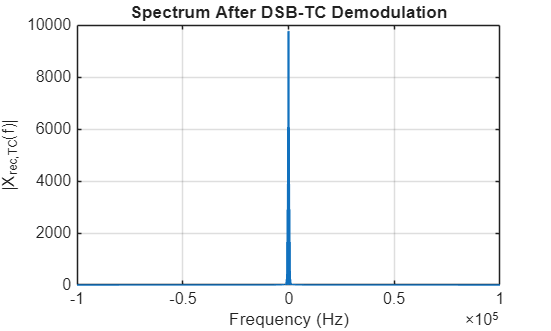

soundsc(x_rec_tc, fs);
pause(4);

%% SPECTRUM AFTER DSB-TC DEMODULATION
Xrec_tc = fftshift(abs(fft(x_rec_tc)));

figure;
plot(f1, Xrec_tc);
title('Spectrum After DSB-TC Demodulation');
xlabel('Frequency (Hz)');
ylabel('|X_{rec,TC}(f)|');
grid on;

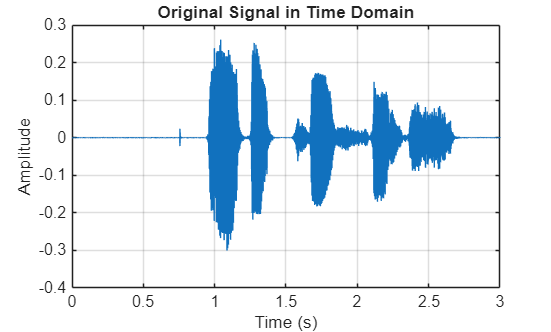


%% =========================
%% OPTIONAL: TIME-DOMAIN PLOTS
%% =========================
figure;
plot(t0, x);
title('Original Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

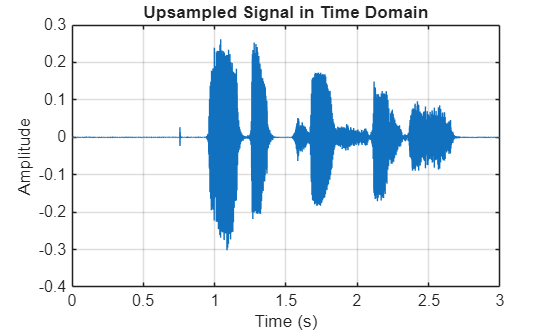


figure;
plot(t, x_up);
title('Upsampled Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

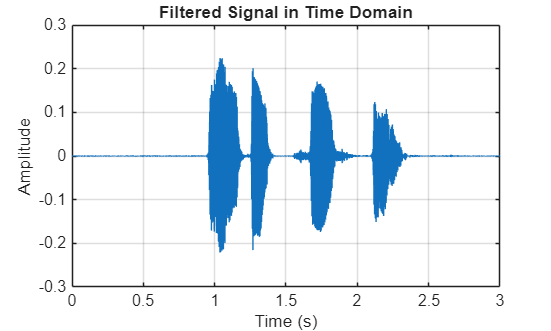


figure;
plot(t, x_filt);
title('Filtered Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

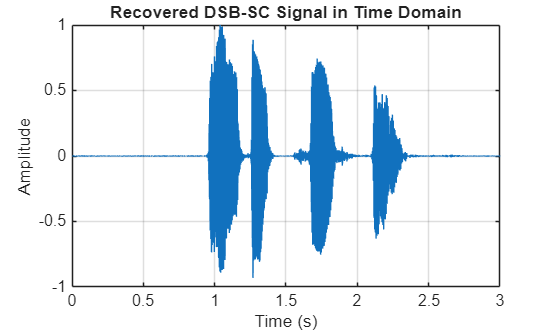


figure;
plot(t, x_rec_sc);
title('Recovered DSB-SC Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

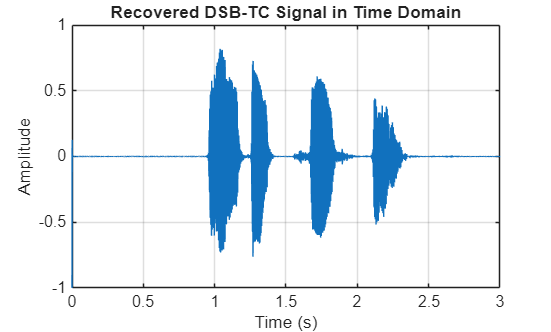


figure;
plot(t, x_rec_tc);
title('Recovered DSB-TC Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;


%% =========================
%% SIMILARITY MEASURES
%% =========================
x_ref = x_filt / max(abs(x_filt) + eps);

L1 = min(length(x_ref), length(x_rec_sc));
mse_sc = mean((x_ref(1:L1) - x_rec_sc(1:L1)).^2);
corr_sc = corr(x_ref(1:L1), x_rec_sc(1:L1));

L2 = min(length(x_ref), length(x_rec_tc));
mse_tc = mean((x_ref(1:L2) - x_rec_tc(1:L2)).^2);
corr_tc = corr(x_ref(1:L2), x_rec_tc(1:L2));

fprintf('DSB-SC -> MSE = %.6f, Correlation = %.6f\n', mse_sc, corr_sc);

DSB-SC -> MSE = 0.035411, Correlation = 0.303513


fprintf('DSB-TC -> MSE = %.6f, Correlation = %.6f\n', mse_tc, corr_tc);

DSB-TC -> MSE = 0.030250, Correlation = 0.302123



%% =========================
%% CARRIER FREQUENCY SHIFT TEST
%% =========================
df_list = [0 5 10 20 30 40 50 75 100 150 200 300 400 500 600 700 800 900 1000];  % Hz

mse_shift_sc = zeros(size(df_list));
corr_shift_sc = zeros(size(df_list));

mse_shift_tc = zeros(size(df_list));
corr_shift_tc = zeros(size(df_list));

for k = 1:length(df_list)
    df = df_list(k);

    %% DSB-SC with shifted carrier
    r_sc_shift = s_sc .* (2*cos(2*pi*(fc + df)*t));
    x_rec_sc_shift = filter(b, a, r_sc_shift);
    x_rec_sc_shift = x_rec_sc_shift / max(abs(x_rec_sc_shift) + eps);

    Ls = min(length(x_ref), length(x_rec_sc_shift));
    mse_shift_sc(k) = mean((x_ref(1:Ls) - x_rec_sc_shift(1:Ls)).^2);
    corr_shift_sc(k) = corr(x_ref(1:Ls), x_rec_sc_shift(1:Ls));

    %% DSB-TC with shifted carrier
    r_tc_shift = s_tc .* (2*cos(2*pi*(fc + df)*t));
    x_rec_tc_shift = filter(b, a, r_tc_shift);

    % remove DC for fair comparison
    x_rec_tc_shift = x_rec_tc_shift - mean(x_rec_tc_shift);
    x_rec_tc_shift = x_rec_tc_shift / max(abs(x_rec_tc_shift) + eps);

    Lt = min(length(x_ref), length(x_rec_tc_shift));
    mse_shift_tc(k) = mean((x_ref(1:Lt) - x_rec_tc_shift(1:Lt)).^2);
    corr_shift_tc(k) = corr(x_ref(1:Lt), x_rec_tc_shift(1:Lt));
end

%% DISPLAY RESULTS
fprintf('\nCarrier Frequency Shift Test:\n');


Carrier Frequency Shift Test:


fprintf('df(Hz)\tSC Corr\t\tSC MSE\t\tTC Corr\t\tTC MSE\n');

df(Hz)	SC Corr		SC MSE		TC Corr		TC MSE


for k = 1:length(df_list)
    fprintf('%d\t%.6f\t%.6f\t%.6f\t%.6f\n', ...
        df_list(k), corr_shift_sc(k), mse_shift_sc(k), ...
        corr_shift_tc(k), mse_shift_tc(k));
end

0	0.303513	0.035411	0.302123	0.030250
5	0.046877	0.044700	0.005475	0.218807
10	0.043783	0.037183	0.005117	0.184658
20	0.008665	0.039817	0.000463	0.199001
30	-0.005324	0.039982	-0.000549	0.186100
40	-0.005947	0.038742	-0.000340	0.180222
50	0.009370	0.043079	-0.001525	0.212648
75	-0.004652	0.040486	0.000693	0.192345
100	-0.006648	0.038532	-0.001235	0.203263
150	0.002903	0.042112	-0.000317	0.208454
200	-0.078280	0.042165	-0.084626	0.200705
300	0.000445	0.044193	-0.005267	0.207455
400	-0.157160	0.047653	0.075354	0.203964
500	0.000998	0.042473	-0.021838	0.221911
600	0.050146	0.040833	-0.010803	0.239477
700	0.006993	0.045433	0.002154	0.250313
800	0.054505	0.039280	0.003502	0.259769
900	0.003076	0.044573	0.001053	0.247279
1000	-0.113165	0.051732	-0.013238	0.231704


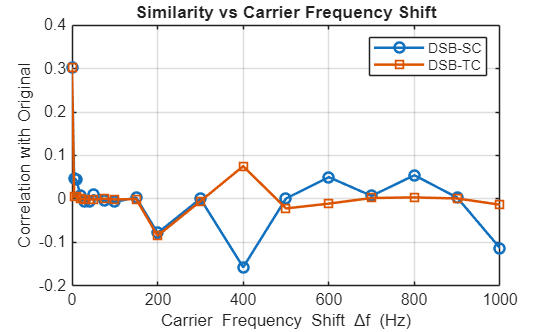


%% PLOT CORRELATION VS SHIFT
figure;
plot(df_list, corr_shift_sc, '-o', 'LineWidth', 1.5);
hold on;
plot(df_list, corr_shift_tc, '-s', 'LineWidth', 1.5);
grid on;
xlabel('Carrier Frequency Shift \Deltaf (Hz)');
ylabel('Correlation with Original');
title('Similarity vs Carrier Frequency Shift');
legend('DSB-SC', 'DSB-TC');

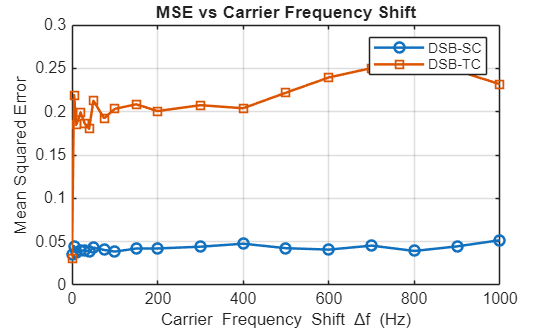


%% PLOT MSE VS SHIFT
figure;
plot(df_list, mse_shift_sc, '-o', 'LineWidth', 1.5);
hold on;
plot(df_list, mse_shift_tc, '-s', 'LineWidth', 1.5);
grid on;
xlabel('Carrier Frequency Shift \Deltaf (Hz)');
ylabel('Mean Squared Error');
title('MSE vs Carrier Frequency Shift');
legend('DSB-SC', 'DSB-TC');


%% =========================
%% LISTEN TO ONE DESTRUCTIVE SHIFT CASE
%% =========================
df_bad = 600;   % changed it after checking the table/plots

r_sc_bad = s_sc .* (2*cos(2*pi*(fc + df_bad)*t));
x_sc_bad = filter(b, a, r_sc_bad);
x_sc_bad = x_sc_bad / max(abs(x_sc_bad) + eps);

disp(['Playing DSB-SC with shifted carrier, df = ' num2str(df_bad) ' Hz']);

Playing DSB-SC with shifted carrier, df = 600 Hz


soundsc(x_sc_bad, fs);
pause(4);

r_tc_bad = s_tc .* (2*cos(2*pi*(fc + df_bad)*t));
x_tc_bad = filter(b, a, r_tc_bad);
x_tc_bad = x_tc_bad - mean(x_tc_bad);
x_tc_bad = x_tc_bad / max(abs(x_tc_bad) + eps);

disp(['Playing DSB-TC with shifted carrier, df = ' num2str(df_bad) ' Hz']);

Playing DSB-TC with shifted carrier, df = 600 Hz


soundsc(x_tc_bad, fs);
pause(4);